# Aligning Gene & Protein Sequences

by **Authors: **[Tony Kabilan Okeke](mailto:tko35@drexel.edu), [Grace Fan](mailto:gf356@drexel.edu)

% Your code and output must only contain code and answers for the following
% questions. You must remove or comment out any analysis/code that is not
% for answering these questions.

## Obtain the gene sequences

Find the hemoglobin subunit alpha-1 genes and proteins for human and Pacific white-sided dolphin. Obtain the sequences of these genes and proteins and download them into the files:

hgenefile=bmes.downloadurl('https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=nuccore&report=fasta&id=568815582&from=176651&to=177522&extrafeat=null&conwithfeat=on','human.hemoglobin.alpha1.gene.fasta');

--- NOTICE: Attempting to download & save url [ https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=nuccore&report=fasta&id=568815582&from=176651&to=177522&extrafeat=null&conwithfeat=on ] to file [ C:/Users/kabil/AppData/Local/Temp/bmes/human.hemoglobin.alpha1.gene.fasta ] ...


dgenefile=bmes.downloadurl('https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=nuccore&report=fasta&id=1511261435&from=13497651&to=13498490&strand=on&extrafeat=null&conwithfeat=on','dolphin.hemoglobin.alpha1.gene.fasta');

--- NOTICE: Attempting to download & save url [ https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=nuccore&report=fasta&id=1511261435&from=13497651&to=13498490&strand=on&extrafeat=null&conwithfeat=on ] to file [ C:/Users/kabil/AppData/Local/Temp/bmes/dolphin.hemoglobin.alpha1.gene.fasta ] ...


hptnfile=bmes.downloadurl('https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=protein&report=fasta&id=4504345&extrafeat=8&conwithfeat=on','human.hemoglobin.alpha1.ptn.fasta');

--- NOTICE: Attempting to download & save url [ https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=protein&report=fasta&id=4504345&extrafeat=8&conwithfeat=on ] to file [ C:/Users/kabil/AppData/Local/Temp/bmes/human.hemoglobin.alpha1.ptn.fasta ] ...


dptnfile=bmes.downloadurl('https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=protein&report=fasta&id=1516118871&extrafeat=8&conwithfeat=on','dolphin.hemoglobin.alpha1.ptn.fasta');

--- NOTICE: Attempting to download & save url [ https://www.ncbi.nlm.nih.gov/sviewer/viewer.cgi?tool=portal&save=file&log$=seqview&db=protein&report=fasta&id=1516118871&extrafeat=8&conwithfeat=on ] to file [ C:/Users/kabil/AppData/Local/Temp/bmes/dolphin.hemoglobin.alpha1.ptn.fasta ] ...


Read in the fasta files.

humgene = fastaread(hgenefile);
dolgene = fastaread(dgenefile);
humptn = fastaread(hptnfile);
dolptn = fastaread(dptnfile);

## Gene Dot plot

Show sequence dotplot of the the human and dolphin genes. Filter out using a window size of 3, and a match number of 3.

seqdotplot(humgene, dolgene, 3, 3)

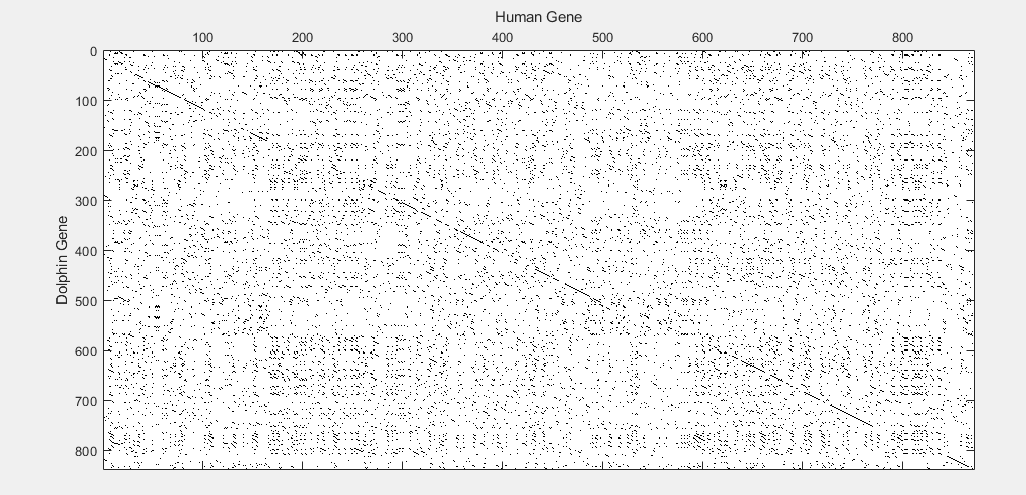

xlabel('Human Gene'), ylabel('Dolphin Gene')

## Protein Dot plot

Show sequence dotplot of the the human and dolphin protein sequences Do not use any filters.

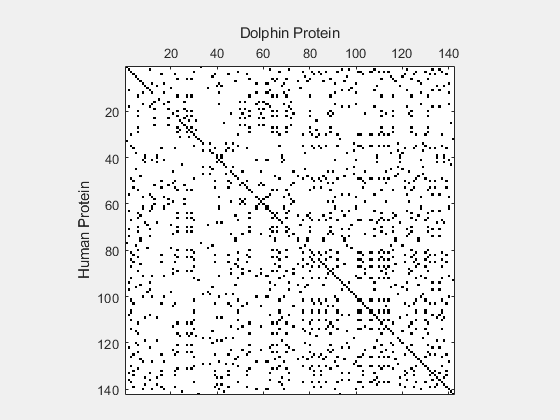

seqdotplot(humptn, dolptn)
xlabel('Dolphin Protein'), ylabel('Human Protein')

## Amino acid percentage frequency

Find out which amino acid has the highest frequency in the **human protein**. Report the single letter amino acid code for it, along with its frequency (as a percentage).

% Define string with Amino Acid Codes
aa = 'ARNDCEQGHILKMFPSTWYV';
% Determine how many time each amino acid occurs
ct = arrayfun(@(x) sum(humptn.Sequence == x), aa);
% Convert counts to percentages
ct = ct / sum(ct) * 100;
% Print results
fprintf('Highest Frequency Amino Acid: %s at %.2f%%', aa(ct == max(ct)), max(ct))

Highest Frequency Amino Acid: A at 14.79%

## Alignment of Genes

Perform global alignment of the gene sequences (use default parameters). Show the alignment score and up to first **60** columns of the alignment.

% Compute global alignment score
[score, align] = nwalign(humgene, dolgene, 'alphabet', 'nt');
fprintf('Global Alignment Score: %.2f', score)

Global Alignment Score: 581.25

% Print first 60 columns of alignment
align(:,1:60)

ans = 3×60 char array
    '--CAT---AAACC---C-T---GG--CGCGCTC-G-CGGCCCGGCACTCTTCTGGTCC--'
    '  | |      ||   | |   ||  ||||| | | | |||| |||| ||||||||||  '
    'CCCCTCGCGCCCCAGGCATAAAGGCTCGCGCACTGCCAGCCCTGCACGCTTCTGGTCCTG'

Perform local alignments of the gene sequences (use default parameters) Show the alignment score and up to **60** columns of the alignment. 

% Compute local alignment score
[score, align] = swalign(humgene, dolgene, 'alphabet', 'nt');
fprintf('Local Alignment Score: %.2f', score)

Local Alignment Score: 614.25

% Print first 60 columns of alignment
align(:,1:60)

ans = 3×60 char array
    'CATAAACCCTGGCGCGCTCGCGGCCCGGCACTCTTCTGGTCC--CCACAGACTCAGAGAG'
    '||||||  || |||| ||  | |||| |||| ||||||||||   | |||||||||||||'
    'CATAAAGGCTCGCGCACTGCCAGCCCTGCACGCTTCTGGTCCTGACCCAGACTCAGAGAG'

What is the percent identity of the entire alignment (Use the entire alignment for your calculation, not just of first 60 columns)?

% Percent Identity
pct_align = sum(align(2,:) == '|') / size(align, 2) * 100;
fprintf('Percent Identity: %.2f%%', pct_align)

Percent Identity: 75.71%

## Alignment of Proteins

Perform **global alignment** of the protein sequences. Use PAM30 substitution matrix, and an affine gap penalty with gap opening penalty of 8 and gap extension penalty of 1. Show the alignment score and the first **60** columns of the alignment. 

% Compute global alignment score
[score, align] = nwalign(humptn, dolptn, 'alphabet', 'aa', 'ScoringMatrix', pam30, 'GapOpen', 8, 'ExtendGap', 1);
fprintf('Global Alignment Score: %.2f', score)

Global Alignment Score: 874.00

% Print first 60 columns of alignment
align(:,1:60)

ans = 3×60 char array
    'MVLSPADKTNVKAAWGKVGAHAGEYGAEALERMFLSFPTTKTYFPHFDLSHGSAQVKGHG'
    '||||||||||||  | |:| |: ||||||||||| :||:||||| |||| |||||:||||'
    'MVLSPADKTNVKGTWSKIGNHSAEYGAEALERMFINFPSTKTYFSHFDLGHGSAQIKGHG'

What is the percent identity of the entire alignment (not just of first 60 columns)?

% Percent Identity
pct_align = sum(align(2,:) == '|') / size(align, 2) * 100;
fprintf('Percent Identity: %.2f%%', pct_align)

Percent Identity: 83.80%

## Custom substitution matrix

Given the DNA sequences ACGTATCGCGTATA and GATGCTCTCGGAAA, find the optimal local alignment and its score. Matches, mismatches, and gaps are scored as +1, 0, and -1, respectively. You can use swalign() to solve this problem. You need to specity the 'alphabet' to be nucleotide and provide your own substitution matrix using the 'ScoringMatrix' parameter. See the documentation for swalign().

seq1 = 'ACGTATCGCGTATA';
seq2 = 'GATGCTCTCGGAAA';

% Create substitution matrix
sm = eye( size(blosum62) );

% Perform alignment
[score, align] = swalign(seq1, seq2, 'alphabet', 'nt', 'ScoringMatrix', sm, 'Gap', 1)

score = 7

align = 3×14 char array
    'ACGTATCGCGTATA'
    '|:| :||:||:|:|'
    'ATG-CTCTCGGAAA'